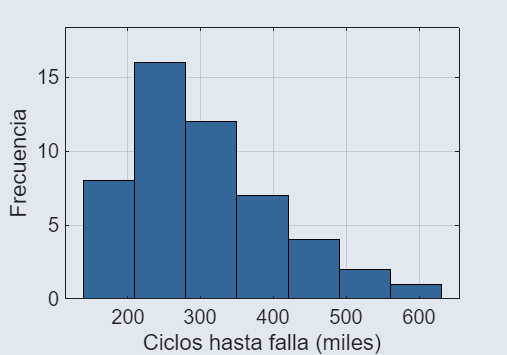

datos = [163, 392, 269, 366, 605, 299, 287, 162, 222, 287, ...
         348, 405, 253, 159, 227, 483, 206, 273, 509, 141, ...
         319, 537, 211, 302, 483, 182, 294, 378, 344, 277, ...
         204, 284, 250, 280, 248, 425, 386, 234, 310, 224, ...
         273, 245, 339, 250, 275, 364, 262, 480, 197, 373];

k = 7;
ancho = 70;
limite_inf = 140;
bordes = limite_inf : ancho : (limite_inf + k*ancho);

color_fondo = [226 232 240] / 255;

figure('Color', color_fondo);
set(gcf, 'Units', 'inches', 'Position', [0 0 5 3.5]);
h = histogram(datos, bordes, 'FaceColor', [0.2 0.4 0.6], ...
    'FaceAlpha', 1, 'EdgeColor', 'black');
set(gca, 'FontSize', 12, 'Color', 'none');
xlabel('Ciclos hasta falla (miles)');
ylabel('Frecuencia');
ylim([0, max(h.Values) * 1.15]);  % margen superior
grid on;
box on;

set(gcf, 'Units', 'inches', 'Position', [0 0 5 3.5]);
exportgraphics(gcf, 'histograma_rodamientos.png', 'Resolution', 300);